# Lyapunov function candidate and possible DOA

## Parameters

close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
ht = sqrt(g * mass / (Kt * 4));


n_inputs = 4;			% number of inputs
n_states = 4;			% number of states 4 (vectors)
state_dim = 3;			% dimension of each state

## Dynamics

let the torque kinematics (transform from input to angular acceleration) be

        
$$\tau_k = \pmatrix{1 & 0 & -1 & 0 \cr 0 & -1 & 0 & 1 \cr -1 & 1 & -1 & 1}$$
 

Forces:

	
$$^NT_p = ^N\hat{z}_{B}\; K_t \Sigma^4_{i=1}u_i^2$$


	
$$^B\tau_p = K_t \;l\;\tau_k\;u^2$$


	
$$^NF_g = -massg \hat{z}_N$$


	
$$^NF_w = w_1\hat{x}_N + w_2\hat{y}_N + w_3\hat{z}_N$$


	
$$^B\tau_w = g_1\hat{x}_N + g_2\hat{y}_N + g_3\hat{z}_N$$


	
$$^NF_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; ^N\dot{r}$$
 

	
$$^B\tau_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; \omega$$
 

EOM:

        $\ddot{r} = (T_p + F_g )\; / \; mass$  **Just realized I need to be dividing by the mass (it's pretty late)

        
$$\dot{\omega} = I^{-1}(-[\tilde{\omega}]I\omega +\tau)$$
 

As a state-space model

Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = T_p + F_g + F_w + F_d$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} = I_b^{-1}(-[\tilde{x_4}]\bar{I}x_4+\tau_p + \tau_w + \tau_d)$$


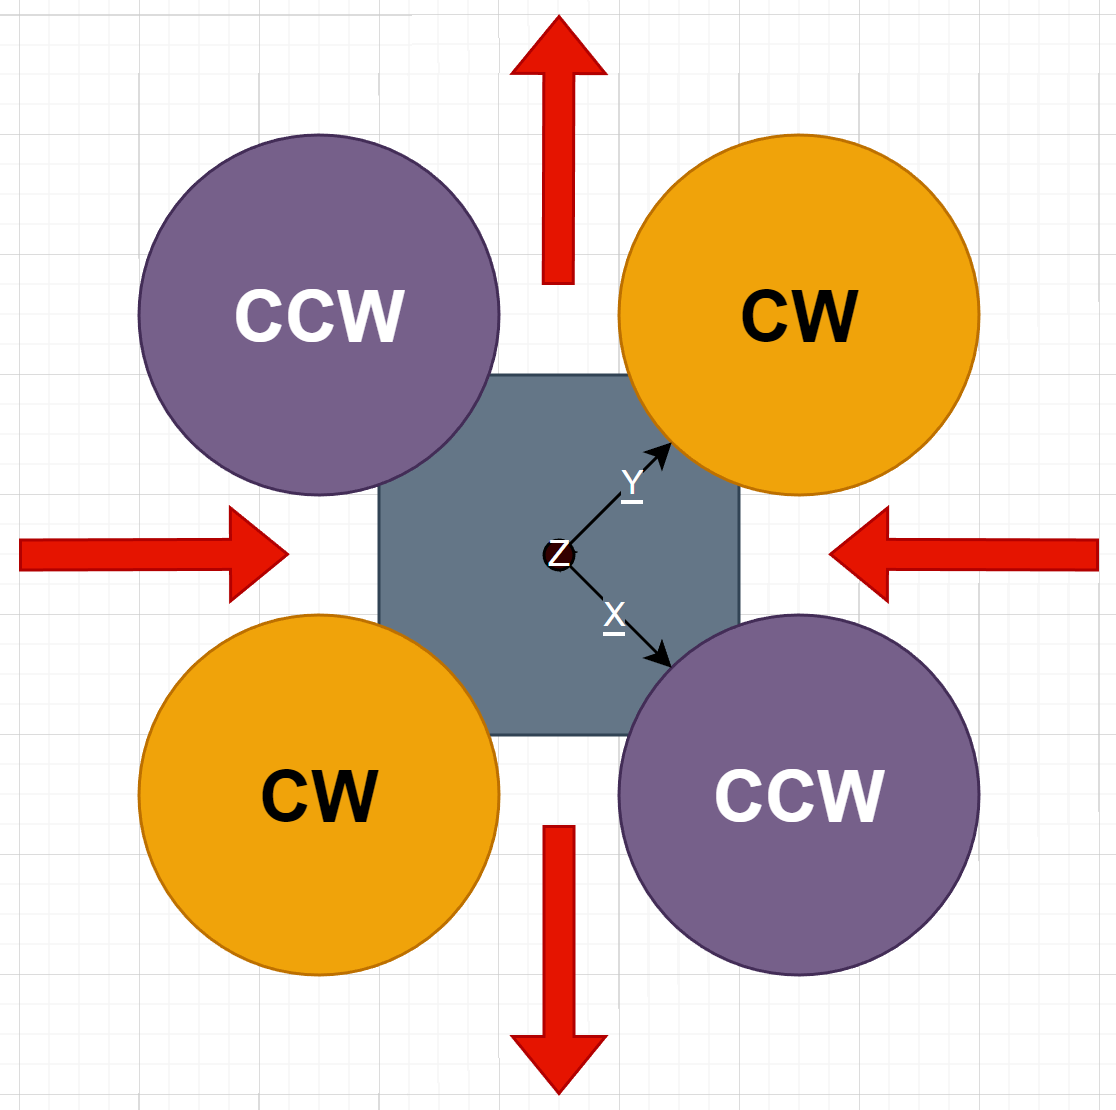

    Including this diagram to highlight a possible interpretation of the plots below. In most cases $\dot{\omega}$ can only escape the domain contained within the sphere when the angular acceleration about the inflow axis is high. In addition a large $\omega$ will make $\dot{V}(x)$ positive in these directions.

## Lyapunov levels for $\omega = [0:\omega_{max}]$ and $q = 0$

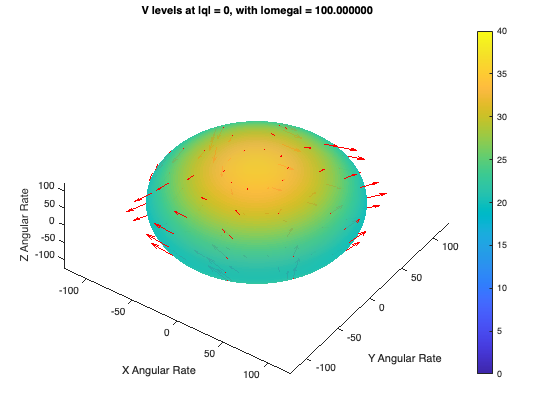

frames = 100;
samples = 100;

% set gains here
gatt = 0;
grat = 10;

tau_k = [1  0 -1  0;
         0 -1  0  1;
	    -10 10  -10  10];
Katt = gatt * pinv(tau_k);

w0 = 0;
wmax = 100;
qr = [0; 0; 0];

Zero = zeros(samples, samples);
window_limits = [-1.25,  1.25];

figure, hold on
colorbar()
view([35 65])
clim([0 40])
xlabel("X Angular Rate")
ylabel("Y Angular Rate")
zlabel("Z Angular Rate")
qv = quiver3(0, 0, 0, 0, 0, 0);
s = surf(zeros(10,10), zeros(10,10), zeros(10,10), 0, "EdgeColor", "none", "FaceAlpha", 0.0);

Q1 = Zero;
Q2 = Zero;
Q3 = Zero;

for radius = linspace(w0, wmax, frames)
	[W1, W2, W3] = sphere(samples - 1);
	W1 = W1 * radius;
	W2 = W2 * radius;
	W3 = W3 * radius;
    
    delete(s)
	V = Rufous_Lyapunov(Q1, Q2, Q3, W1, W2, W3, qr, Ib, Katt);
	s = surf(W1, W2, W3, V, "EdgeColor", "none", "FaceAlpha", 0.9);

	W1s = W1(1:10:end,1:10:end);
	W2s = W2(1:10:end,1:10:end);
	W3s = W3(1:10:end,1:10:end);
	Q1s = Q1(1:10:end,1:10:end);
	Q2s = Q2(1:10:end,1:10:end);
	Q3s = Q3(1:10:end,1:10:end);

	[U1, U2, U3, U4] = meshgrid_control_law(Q1s, Q2s, Q3s, W1s, W2s, W3s, g, mass, Kt, gatt, grat);
	[w1, w2, w3, dw1, dw2, dw3] = attitude_dynamics(W1s, W2s, W3s, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);

    delete(qv);
	qv = quiver3(W1s, W2s, W3s, dw1, dw2, dw3, 'r');

	title(sprintf("V levels at |q| = 0, with |omega| = %f\n", radius))
	xlim(max(radius, 1e-10) * window_limits)
	ylim(max(radius, 1e-10) * window_limits)
	zlim(max(radius, 1e-10) * window_limits)
	pause(0.001);
end

## Lyapunov levels for $\omega = 0$ and $q = [0 :q_{max}]$

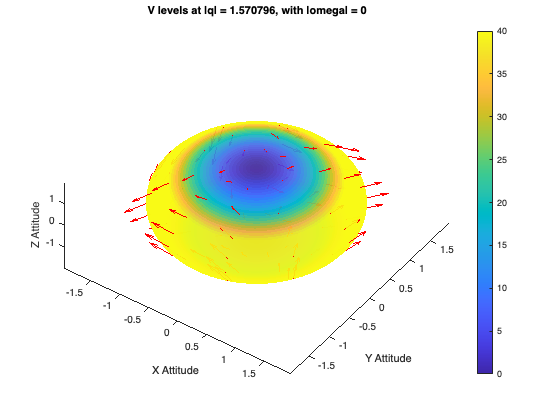

frames = 100;
samples = 100;

% set gains here
gatt = 10;
grat = 0;

tau_k = [1  0 -1  0;
         0 -1  0  1;
	    -10 10  -10  10];
Katt = gatt * pinv(tau_k);

q0 = 0;
qmax = pi/2;
qr = [0; 0; 0];

Zero = zeros(samples, samples);
window_limits = [-1.25,  1.25];

figure, hold on
colorbar()
view([35 65])
clim([0 40])
xlabel("X Attitude")
ylabel("Y Attitude")
zlabel("Z Attitude")
qv = quiver3(0, 0, 0, 0, 0, 0);
s = surf(zeros(10,10), zeros(10,10), zeros(10,10), 0, "EdgeColor", "none", "FaceAlpha", 0.0);

W1 = Zero;
W2 = Zero;
W3 = Zero;

for radius = linspace(q0, qmax, frames)
	[Q1, Q2, Q3] = sphere(samples - 1);
	Q1 = Q1 * radius;
	Q2 = Q2 * radius;
	Q3 = Q3 * radius;

    delete(s)
	V = Rufous_Lyapunov(Q1, Q2, Q3, W1, W2, W3, qr, Ib, Katt);
	s = surf(Q1, Q2, Q3, V, "EdgeColor", "none", "FaceAlpha", 0.9);

	delete(qv);
	W1s = W1(1:10:end,1:10:end);
	W2s = W2(1:10:end,1:10:end);
	W3s = W3(1:10:end,1:10:end);
	Q1s = Q1(1:10:end,1:10:end);
	Q2s = Q2(1:10:end,1:10:end);
	Q3s = Q3(1:10:end,1:10:end);

	[U1, U2, U3, U4] = meshgrid_control_law(Q1s, Q2s, Q3s, W1s, W2s, W3s, g, mass, Kt, gatt, grat);
	[w1, w2, w3, dw1, dw2, dw3] = attitude_dynamics(W1s, W2s, W3s, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);

	qv = quiver3(Q1s, Q2s, Q3s, dw1, dw2, dw3, 'r');

	title(sprintf("V levels at |q| = %f, with |omega| = 0\n", radius))
	xlim(max(radius, 1e-10) * window_limits)
	ylim(max(radius, 1e-10) * window_limits)
	zlim(max(radius, 1e-10) * window_limits)
	pause(0.001);
end

## Lyapunov levels for $\omega = [-\omega_{max}: 0]$ and $q = [0 :q_{max}]$

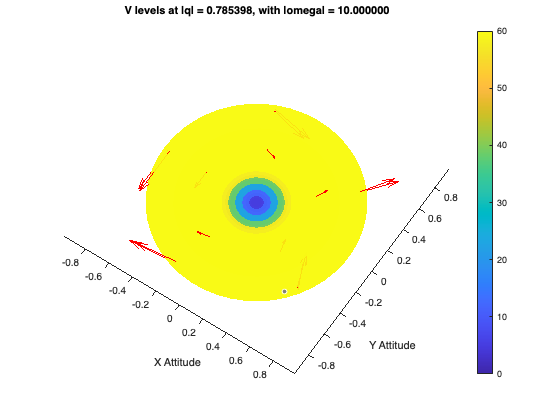

frames = 100;
samples = 50;

% set gains here
gatt = 60;
grat = 100;

tau_k = [1  0 -1  0;
         0 -1  0  1;
	    -10 10  -10  10];
Katt = gatt * pinv(tau_k);

q0 = 1e-10;
qmax = pi/4;
w0 = 0;
wmax = 10;
qr = [0; 0; 0];

window_limits = [-1.25,  1.25];

figure, hold on
colorbar()
view([35 65])
clim([0 60])
xlabel("X Attitude")
ylabel("Y Attitude")
zlabel("Z Attitude")
qv = quiver3(0, 0, 0, 0, 0, 0);
s = surf(zeros(10,10), zeros(10,10), zeros(10,10), 0, "EdgeColor", "none", "FaceAlpha", 0.0);

for radius = linspace(q0, qmax, 5)
	[Q1, Q2, Q3] = sphere(samples - 1);
	Q1 = Q1 * radius;
	Q2 = Q2 * radius;
	Q3 = Q3 * radius;
	for omega = linspace(w0, wmax, frames)
		[W1, W2, W3] = sphere(samples - 1);
		W1 = W1 * omega;
		W2 = W2 * omega;
		W3 = W3 * omega;

        delete(s)
		V = Rufous_Lyapunov(Q1, Q2, Q3, W1, W2, W3, qr, Ib, Katt);
		surf(Q1, Q2, Q3, V, "EdgeColor", "none", "FaceAlpha", 0.9);
	
		delete(qv);
		W1s = W1(1:10:end,1:10:end);
		W2s = W2(1:10:end,1:10:end);
		W3s = W3(1:10:end,1:10:end);
		Q1s = Q1(1:10:end,1:10:end);
		Q2s = Q2(1:10:end,1:10:end);
		Q3s = Q3(1:10:end,1:10:end);
	
		[U1, U2, U3, U4] = meshgrid_control_law(Q1s, Q2s, Q3s, W1s, W2s, W3s, g, mass, Kt, gatt, grat);
		[w1, w2, w3, dw1, dw2, dw3] = attitude_dynamics(W1s, W2s, W3s, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);

		qv = quiver3(Q1s, Q2s, Q3s, dw1, dw2, dw3, 'r');
	
		title(sprintf("V levels at |q| = %f, with |omega| = %f\n", radius, omega))
		xlim(max(radius, 1e-10) * window_limits)
		ylim(max(radius, 1e-10) * window_limits)
		zlim(max(radius, 1e-10) * window_limits)
		pause(0.001);
	end
end

## Lyapunov gradient for $\omega = [0:\omega_{max}]$, $q = 0$ and $u = h_t + control$

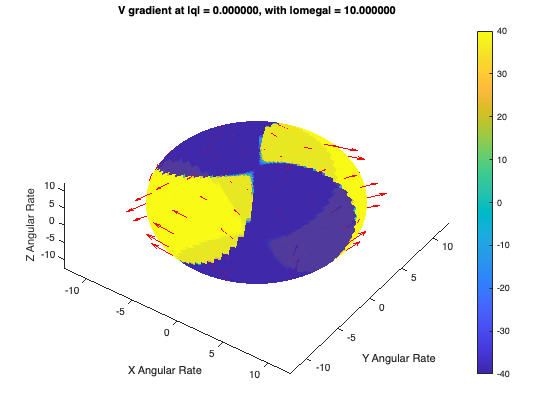

frames = 100;
samples = 100;

% set gains here
gatt = 10;
grat = 75;

tau_k = [1  0 -1  0;
         0 -1  0  1;
	    -10 10  -10  10];
Katt = gatt * pinv(tau_k);

w0 = 0;
wmax = 10;

window_limits = [-1.25,  1.25];

figure, hold on
colorbar()
view([35 65])
clim([-40 40])
xlabel("X Angular Rate")
ylabel("Y Angular Rate")
zlabel("Z Angular Rate")
qv = quiver3(0, 0, 0, 0, 0, 0);
s = surf(zeros(10,10), zeros(10,10), zeros(10,10), zeros(10,10), "EdgeColor", "none", "FaceAlpha", 0.0);

Q1 = zeros(samples, samples);
Q2 = zeros(samples, samples);
Q3 = zeros(samples, samples);
for omega = linspace(w0, wmax, frames)
	[W1, W2, W3] = sphere(samples - 1);
	W1 = W1 * omega;
	W2 = W2 * omega;
	W3 = W3 * omega;

	[U1, U2, U3, U4] = meshgrid_control_law(Q1, Q2, Q3, W1, W2, W3, g, mass, Kt, gatt, grat);
	[~, ~, ~, dw1, dw2, dw3] = attitude_dynamics(W1, W2, W3, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);
	
    delete(s)
    V = Rufous_Lyapunov_dot(Q1, Q2, Q3, W1, W2, W3, dw1, dw2, dw3, Ib, Katt);
	s = surf(W1, W2, W3, V, "EdgeColor", "none", "FaceAlpha", 0.9);

	delete(qv);
	W1s = W1(1:10:end,1:10:end);
	W2s = W2(1:10:end,1:10:end);
	W3s = W3(1:10:end,1:10:end);
	Q1s = Q1(1:10:end,1:10:end);
	Q2s = Q2(1:10:end,1:10:end);
	Q3s = Q3(1:10:end,1:10:end);

	[U1, U2, U3, U4] = meshgrid_control_law(Q1s, Q2s, Q3s, W1s, W2s, W3s, g, mass, Kt, gatt, grat);
	[w1, w2, w3, dw1, dw2, dw3] = attitude_dynamics(W1s, W2s, W3s, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);

	qv = quiver3(W1s, W2s, W3s, dw1, dw2, dw3, 'r');

	title(sprintf("V gradient at |q| = %f, with |omega| = %f\n", 0, omega))
	xlim(max(omega, 1e-10) * window_limits)
	ylim(max(omega, 1e-10) * window_limits)
	zlim(max(omega, 1e-10) * window_limits)
	pause(0.001);
end

## Lyapunov gradient for $\omega = 0$, $q = [0 : q_{max}]$ and $u = h_t + control$

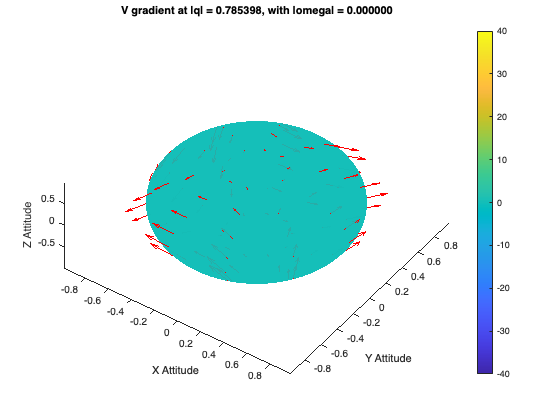

frames = 100;
samples = 100;

% set gains here
gatt = 50;
grat = 75;

tau_k = [1  0 -1  0;
         0 -1  0  1;
	    -10 10  -10  10];
Katt = gatt * pinv(tau_k);

q0 = 0;
qmax = pi/4;

window_limits = [-1.25,  1.25];

figure, hold on
colorbar()
view([35 65])
clim([-40 40])
xlabel("X Attitude")
ylabel("Y Attitude")
zlabel("Z Attitude")
qv = quiver3(0, 0, 0, 0, 0, 0, 'r');
s = surf(zeros(samples, samples), zeros(samples, samples), zeros(samples, samples), "EdgeColor", "none", "FaceAlpha", 0.0);

W1 = zeros(samples, samples);
W2 = zeros(samples, samples);
W3 = zeros(samples, samples);
for radius = linspace(q0, qmax, frames)
	
	[Q1, Q2, Q3] = sphere(samples - 1);
	Q1 = Q1 * radius;
	Q2 = Q2 * radius;
	Q3 = Q3 * radius;

	[U1, U2, U3, U4] = meshgrid_control_law(Q1, Q2, Q3, W1, W2, W3, g, mass, Kt, gatt, grat);
	[~, ~, ~, dw1, dw2, dw3] = attitude_dynamics(W1, W2, W3, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);
	
    delete(s)
    V = Rufous_Lyapunov_dot(Q1, Q2, Q3, W1, W2, W3, dw1, dw2, dw3, Ib, Katt);
	s = surf(Q1, Q2, Q3, V, "EdgeColor", "none", "FaceAlpha", 0.9);

	delete(qv);
	W1s = W1(1:10:end,1:10:end);
	W2s = W2(1:10:end,1:10:end);
	W3s = W3(1:10:end,1:10:end);
	Q1s = Q1(1:10:end,1:10:end);
	Q2s = Q2(1:10:end,1:10:end);
	Q3s = Q3(1:10:end,1:10:end);

	[U1, U2, U3, U4] = meshgrid_control_law(Q1s, Q2s, Q3s, W1s, W2s, W3s, g, mass, Kt, gatt, grat);
	[w1, w2, w3, dw1, dw2, dw3] = attitude_dynamics(W1s, W2s, W3s, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);

	qv = quiver3(Q1s, Q2s, Q3s, dw1, dw2, dw3, 'r');

	title(sprintf("V gradient at |q| = %f, with |omega| = %f\n", radius, 0))
	xlim(max(radius, 1e-10) * window_limits)
	ylim(max(radius, 1e-10) * window_limits)
	zlim(max(radius, 1e-10) * window_limits)
	pause(0.001);
end

## Lyapunov gradient for $\omega = [0:\omega_{max}]$, $q = [0 : q_{max}]$ and $u = h_t + control$

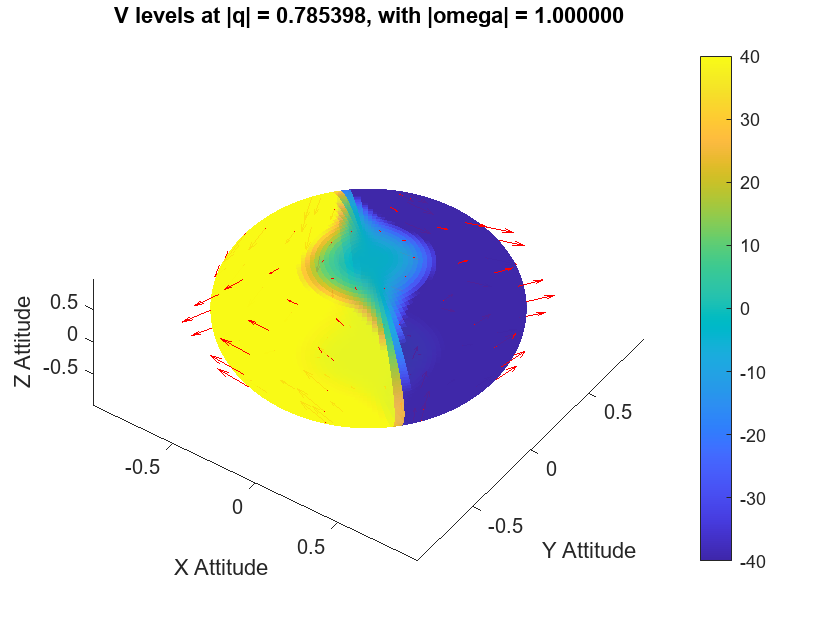

frames = 100;
samples = 100;

% set gains here
gatt = 60;
grat = 100;

tau_k = [1  0 -1  0;
         0 -1  0  1;
	    -10 10  -10  10];
Katt = gatt * pinv(tau_k);

q0 = 1e-10;
qmax = pi/4;
w0 = 0;
wmax = 1;
qr = [0; 0; 0];

window_limits = [-1.25,  1.25];

figure, hold on
colorbar()
view([35 65])
clim([-40 40])
xlabel("X Attitude")
ylabel("Y Attitude")
zlabel("Z Attitude")
qv = quiver3(0, 0, 0, 0, 0, 0, 'r');
s = surf(zeros(samples, samples), zeros(samples, samples), zeros(samples, samples), "EdgeColor", "none", "FaceAlpha", 0.0);


for radius = linspace(q0, qmax, 5)
	[Q1, Q2, Q3] = sphere(samples - 1);
	Q1 = Q1 * radius;
	Q2 = Q2 * radius;
	Q3 = Q3 * radius;
	for omega = linspace(w0, wmax, frames)
		[W1, W2, W3] = sphere(samples - 1);
		W1 = W1 * omega;
		W2 = W2 * omega;
		W3 = W3 * omega;

		[U1, U2, U3, U4] = meshgrid_control_law(Q1, Q2, Q3, W1, W2, W3, g, mass, Kt, gatt, grat);
		[~, ~, ~, dw1, dw2, dw3] = attitude_dynamics(W1, W2, W3, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);
		
        delete(s)
        V = Rufous_Lyapunov_dot(Q1, Q2, Q3, W1, W2, W3, dw1, dw2, dw3, Ib, Katt);
		s = surf(Q1, Q2, Q3, V, "EdgeColor", "none", "FaceAlpha", 0.9);
	
		delete(qv);
		W1s = W1(1:10:end,1:10:end);
		W2s = W2(1:10:end,1:10:end);
		W3s = W3(1:10:end,1:10:end);
		Q1s = Q1(1:10:end,1:10:end);
		Q2s = Q2(1:10:end,1:10:end);
		Q3s = Q3(1:10:end,1:10:end);
	
		[U1, U2, U3, U4] = meshgrid_control_law(Q1s, Q2s, Q3s, W1s, W2s, W3s, g, mass, Kt, gatt, grat);
		[w1, w2, w3, dw1, dw2, dw3] = attitude_dynamics(W1s, W2s, W3s, U1, U2, U3, U4, Ixx, Iyy, Izz, Kt, l);
	
		qv = quiver3(Q1s, Q2s, Q3s, dw1, dw2, dw3, 'r');
	
		title(sprintf("V levels at |q| = %f, with |omega| = %f\n", radius, omega))
		xlim(max(radius, 1e-10) * window_limits)
		ylim(max(radius, 1e-10) * window_limits)
		zlim(max(radius, 1e-10) * window_limits)
		pause(0.001);
	end
end

## Functions

function [dtheta, dphi, dpsi, ddtheta, ddphi, ddpsi] = attitude_dynamics(w1, w2, w3, u1, u2, u3, u4, Ixx, Iyy, Izz, Kt, l)
	dtheta = w1;
	dphi = w2;
	dpsi = w3;
	ddtheta = ((w2.* w3 * (-Iyy - Izz)) + (Kt * l * (max(u2,0).^2 - max(u4,0).^2))) / Ixx;
	ddphi = ((w1 .* w3 * (Ixx + Izz)) + (Kt * l * (max(u3,0).^2 - max(u1,0).^2))) / Iyy;
	ddpsi = ((w1 .* w2 * (-Ixx + Iyy)) + (Kt * l * (-max(u1,0).^2 + max(u2,0).^2 - max(u3,0).^2 + max(u4,0).^2))) / Izz;
end

function [u1, u2, u3, u4] = meshgrid_control_law(q1, q2, q3, w1, w2, w3, g, mass, Kt, gatt, grat)
	tau_k = [1  0 -1  0;
	         0 -1  0  1;
		    -10 10  -10  10];
	tilt = abs(cos(q1) .* cos(q2));
	ht = sqrt(g * mass / (Kt * 4)) * tilt;
	Katt = gatt * pinv(tau_k);
	Krat = grat * pinv(tau_k);
	u1 = ht - ((Katt(1,1) * q1) + (Katt(1,2) * q2) + (Katt(1,3) * q3) + (Krat(1,1) * w1) + (Krat(1,2) * w2) + (Krat(1,3) * w3));
	u2 = ht - ((Katt(2,1) * q1) + (Katt(2,2) * q2) + (Katt(2,3) * q3) + (Krat(2,1) * w1) + (Krat(2,2) * w2) + (Krat(2,3) * w3));
	u3 = ht - ((Katt(3,1) * q1) + (Katt(3,2) * q2) + (Katt(3,3) * q3) + (Krat(3,1) * w1) + (Krat(3,2) * w2) + (Krat(3,3) * w3));
	u4 = ht - ((Katt(4,1) * q1) + (Katt(4,2) * q2) + (Katt(4,3) * q3) + (Krat(4,1) * w1) + (Krat(4,2) * w2) + (Krat(4,3) * w3));
end